## **Blade properties**

load("Bladedata_IEA15MW.mat");

### **Plot chord, twist and pre-bending**

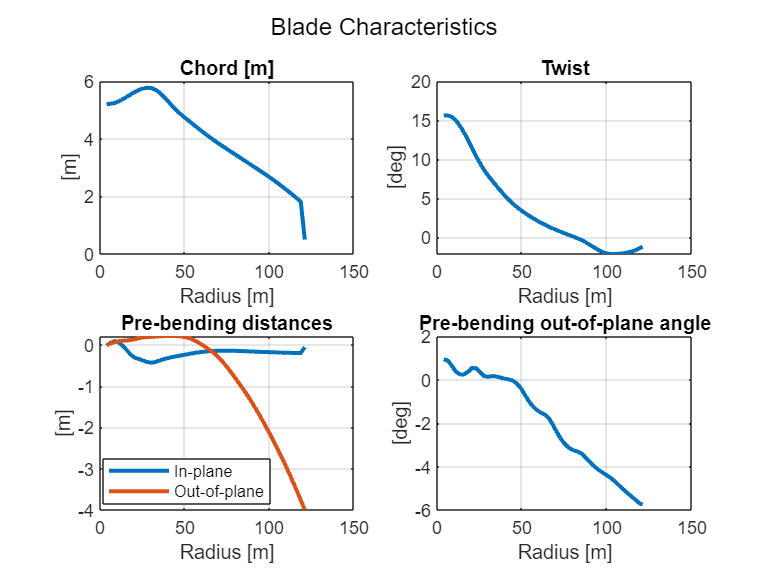

clf
figure()
subplot(2,2,1)
plot(bladedata.radius,bladedata.chord,'LineWidth',2)
xlabel("Radius [m]");
ylabel("[m]")
title("Chord [m]")
grid on

subplot(2,2,2)
plot(bladedata.radius,bladedata.twist,'LineWidth',2)
xlabel("Radius [m]");
ylabel("[deg]")
title("Twist")
grid on

subplot(2,2,3)
plot(bladedata.radius,bladedata.BlSwpAC,'LineWidth',2)
hold on
plot(bladedata.radius,bladedata.BlCrvAC,'LineWidth',2)
xlabel("Radius [m]");
ylabel("[m]")
title("Pre-bending distances")
legend('In-plane','Out-of-plane','Location','best')
grid on

subplot(2,2,4)
plot(bladedata.radius,bladedata.BlCrvAng,'LineWidth',2)
xlabel("Radius [m]");
ylabel("[deg]")
title("Pre-bending out-of-plane angle")
grid on

sgtitle('Blade Characteristics', 'FontSize', 12);

### Plot lift and drag coefficents

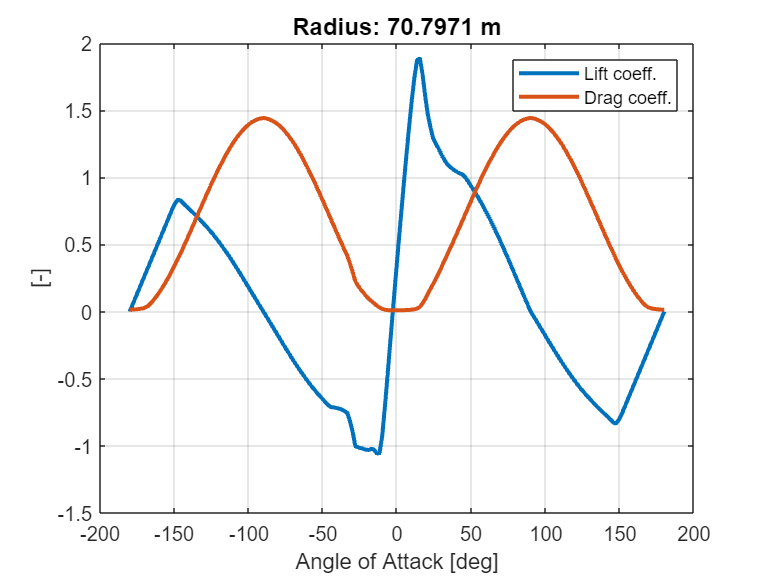

section=29;
clf
plot(bladedata.airfoil(:,1,bladedata.airfoil_index(section)),...
    bladedata.airfoil(:,2,bladedata.airfoil_index(section)),'LineWidth',2)
hold on
plot(bladedata.airfoil(:,1,bladedata.airfoil_index(section)),...
    bladedata.airfoil(:,3,bladedata.airfoil_index(section)),'LineWidth',2)
xlabel("Angle of Attack [deg]");
ylabel("[-]");
title(['Radius: ' num2str(bladedata.radius(section)) ' m'], 'FontSize', 12);
legend(["Lift coeff.","Drag coeff."],Location="northeast");
grid on
hold off